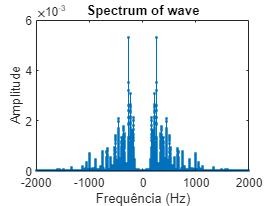

load Guitar03.mat;

Ta = 1/fa;


figure
[X,f] = Espetro(x,Ta);
xlim([-2e3 2e3]);
title('Spectrum of wave');
hold on

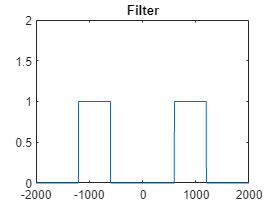


filteredX = Filter(X,f,[600 1200]);

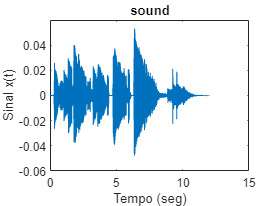


figure(3)
y = Reconstroi(filteredX,f);
title('sound');

sound(real(y),fa)



function [x,Ta] = Reconstroi(X,f)

  N = length(X);

  X = ifftshift(X);
  x = ifft(X)*N;

  fa = f(end)*2;
  Ta = 1/fa;


  t = [0:(N-1)]'*Ta;

  figure;
  plot(t,x);
  xlabel("Tempo (seg)");
  ylabel("Sinal x(t)");
end




function filteredX = Filter(X,f,limits)


% X, f -> [X,f] = Espetro(x,Ta);
% limits -> [400 600] (ex)

N=length(f);

%freqs que queremos do sinal
min = limits(1);
max = limits(2);

H = zeros(N,1);
H(f > min & f < max) = 1; %o que queremos
H(f > -max & f < -min) = 1; % parte negativa

figure
plot(f, H)
title('Filter');
xlim([-2e3 2e3]);
ylim([0 2]);
  
filteredX = H.*X;

end



function [X,f] = Espetro(x,Ta)
%ESPETRO retorna e apresenta o espetro (amplitude apenas) 
%de um sinal passado através do seu vetor de amostras

%muitas vezes isto ira dar jeito 
%xlim([-2e3 2e3]);

N = length(x);      %numero amostras
Fa = 1/Ta;
  

X = fft(x)/N;
X = fftshift(X);

  if rem(N,2)==0
      f=[-N/2:N/2-1] * (Fa/N);
  else
      f=[-(N-1)/2:(N-1)/2] * (Fa/N);
  end
  
stem(f,abs(X),'.');
xlabel('Frequência (Hz)')
ylabel('Amplitude')
title('Amplitude em função da frequência')

end
